startup_rvc

Robotics, Vision & Control: (c) Peter Corke 1992-2019 http://www.petercorke.com
Neither Robotics Toolbox or MachineVision Toolbox found in C:\Users\ninja\AppData\Roaming\MathWorks\MATLAB Add-Ons\Toolboxes\Robotics Toolbox for MATLAB\lib


import ETS3.*
syms tet v gam

gam = pi/8

gam = 0.3927

base = [0.3 0.5 0.2]

base =     0.3000    0.5000    0.2000


rThf = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0.15 0.2 0.1 1]'

rThf =     1.0000         0         0    0.1500
         0    1.0000         0    0.2000
         0         0    1.0000    0.1000
         0         0         0    1.0000


rTvf = [1 0 0 0; 0 1 0 0; 0 0 1 0; -0.15 0.2 0.1 1]'

rTvf =     1.0000         0         0   -0.1500
         0    1.0000         0    0.2000
         0         0    1.0000    0.1000
         0         0         0    1.0000


rThb = [cos(gam) sin(gam) 0 0; -sin(gam) cos(gam) 0 0; 0 0 1 0; 0.15 -0.2 -0.1 1]'

rThb =     0.9239   -0.3827         0    0.1500
    0.3827    0.9239         0   -0.2000
         0         0    1.0000   -0.1000
         0         0         0    1.0000


rTvb = [cos(gam) sin(gam) 0 0; -sin(gam) cos(gam) 0 0; 0 0 1 0; -0.15 -0.2 -0.1 1]'

rTvb =     0.9239   -0.3827         0   -0.1500
    0.3827    0.9239         0   -0.2000
         0         0    1.0000   -0.1000
         0         0         0    1.0000


rTc = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0.25 0.2 1]'

rTc =     1.0000         0         0         0
         0    1.0000         0    0.2500
         0         0    1.0000    0.2000
         0         0         0    1.0000


rTa = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 -0.1 0.2 1]'

rTa =     1.0000         0         0         0
         0    1.0000         0   -0.1000
         0         0    1.0000    0.2000
         0         0         0    1.0000



bevegelse = [v*cos(tet) , v*sin(tet) ,(v/(rThf(2,4)-rThb(2,4)))*tan(gam)];

l(1) = 0;
l(2) = 0.3;
l(3) = 0.3;
l(4) = 0.3;
l(5) = 0;

syms t1 t2 t3 t4 t5 al1 al2 al3 al4 al5

al1=0;
al2=pi/2;
al3=0;
al4=0;
al5=-pi/2;

li1 =  [cos(t1) -sin(t1) 0 0                                    ; sin(t1) cos(t1) 0 0                                     ; 0 0 1 0               ; 0 0 0 1]

$$li1 = \left(\begin{array}{cccc} \cos\left(t_{1}\right) & -\sin\left(t_{1}\right) & 0 & 0\\ \sin\left(t_{1}\right) & \cos\left(t_{1}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

li2 =  [cos(t2) -sin(t2)*cos(al2) sin(t2)*sin(al2) l(2)*cos(t2) ; sin(t2) cos(t2)*cos(al2) -cos(t2)*sin(al2) l(2)*sin(t2) ; 0 sin(al2) cos(al2) 0 ; 0 0 0 1]

$$li2 = \left(\begin{array}{cccc} \cos\left(t_{2}\right) & -\frac{4967757600021511\,\sin\left(t_{2}\right)}{81129638414606681695789005144064} & \sin\left(t_{2}\right) & \frac{3\,\cos\left(t_{2}\right)}{10}\\ \sin\left(t_{2}\right) & \frac{4967757600021511\,\cos\left(t_{2}\right)}{81129638414606681695789005144064} & -\cos\left(t_{2}\right) & \frac{3\,\sin\left(t_{2}\right)}{10}\\ 0 & 1 & \frac{4967757600021511}{81129638414606681695789005144064} & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

li3 =  [cos(t3) -sin(t3)*cos(al3) sin(t3)*sin(al3) l(3)*cos(t3) ; sin(t3) cos(t3)*cos(al3) -cos(t3)*sin(al3) l(3)*sin(t3) ; 0 sin(al3) cos(al3) 0 ; 0 0 0 1]

$$li3 = \left(\begin{array}{cccc} \cos\left(t_{3}\right) & -\sin\left(t_{3}\right) & 0 & \frac{3\,\cos\left(t_{3}\right)}{10}\\ \sin\left(t_{3}\right) & \cos\left(t_{3}\right) & 0 & \frac{3\,\sin\left(t_{3}\right)}{10}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

li4 =  [cos(t4) -sin(t4)*cos(al4) sin(t4)*sin(al4) l(4)*cos(t4) ; sin(t4) cos(t4)*cos(al4) -cos(t4)*sin(al4) l(4)*sin(t4) ; 0 sin(al4) cos(al4) 0 ; 0 0 0 1]

$$li4 = \left(\begin{array}{cccc} \cos\left(t_{4}\right) & -\sin\left(t_{4}\right) & 0 & \frac{3\,\cos\left(t_{4}\right)}{10}\\ \sin\left(t_{4}\right) & \cos\left(t_{4}\right) & 0 & \frac{3\,\sin\left(t_{4}\right)}{10}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

li5 =  [cos(t5) -sin(t5)*cos(al5) sin(t5)*sin(al5) l(5)*cos(t5) ; sin(t5) cos(t5)*cos(al5) -cos(t5)*sin(al5) l(5)*sin(t5) ; 0 sin(al5) cos(al5) 0 ; 0 0 0 1]

$$li5 = \left(\begin{array}{cccc} \cos\left(t_{5}\right) & -\frac{4967757600021511\,\sin\left(t_{5}\right)}{81129638414606681695789005144064} & -\sin\left(t_{5}\right) & 0\\ \sin\left(t_{5}\right) & \frac{4967757600021511\,\cos\left(t_{5}\right)}{81129638414606681695789005144064} & \cos\left(t_{5}\right) & 0\\ 0 & -1 & \frac{4967757600021511}{81129638414606681695789005144064} & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


li10 = [cos(t1) -sin(t1) 0 0                      ; sin(t1) cos(t1) 0 0               ; 0 0 1 0  ; 0 0 0 1]

$$li10 = \left(\begin{array}{cccc} \cos\left(t_{1}\right) & -\sin\left(t_{1}\right) & 0 & 0\\ \sin\left(t_{1}\right) & \cos\left(t_{1}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

li20 = [cos(t2) -sin(t2)*0 sin(t2)*1 l(2)*cos(t2) ; sin(t2) 0 -cos(t2)*1 l(2)*sin(t2) ; 0 1 0 0  ; 0 0 0 1]

$$li20 = \left(\begin{array}{cccc} \cos\left(t_{2}\right) & 0 & \sin\left(t_{2}\right) & \frac{3\,\cos\left(t_{2}\right)}{10}\\ \sin\left(t_{2}\right) & 0 & -\cos\left(t_{2}\right) & \frac{3\,\sin\left(t_{2}\right)}{10}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

li30 = [cos(t3) -sin(t3)*1 0 l(3)*cos(t3)         ; sin(t3) cos(t3) 0 l(3)*sin(t3)    ; 0 0 1 0  ; 0 0 0 1]

$$li30 = \left(\begin{array}{cccc} \cos\left(t_{3}\right) & -\sin\left(t_{3}\right) & 0 & \frac{3\,\cos\left(t_{3}\right)}{10}\\ \sin\left(t_{3}\right) & \cos\left(t_{3}\right) & 0 & \frac{3\,\sin\left(t_{3}\right)}{10}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

li40 = [cos(t4) -sin(t4)*1 0 l(4)*cos(t4)         ; sin(t4) cos(t4) 0 l(4)*sin(t4)    ; 0 0 1 0  ; 0 0 0 1]

$$li40 = \left(\begin{array}{cccc} \cos\left(t_{4}\right) & -\sin\left(t_{4}\right) & 0 & \frac{3\,\cos\left(t_{4}\right)}{10}\\ \sin\left(t_{4}\right) & \cos\left(t_{4}\right) & 0 & \frac{3\,\sin\left(t_{4}\right)}{10}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

li50 = [cos(t5) -sin(t5)*0 -sin(t5) l(5)*cos(t5)  ; sin(t5) 0 cos(t5) l(5)*sin(t5)    ; 0 -1 0 0 ; 0 0 0 1]

$$li50 = \left(\begin{array}{cccc} \cos\left(t_{5}\right) & 0 & -\sin\left(t_{5}\right) & 0\\ \sin\left(t_{5}\right) & 0 & \cos\left(t_{5}\right) & 0\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$ans = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2}\,\cos\left(t_{1}+t_{2}\right) & -\sin\left(t_{1}+t_{2}\right) & -\sigma_{1}\,\cos\left(t_{1}+t_{2}\right) & \frac{3\,\cos\left(t_{1}+t_{2}\right)\,\sigma_{3}}{10}\\ \sigma_{2}\,\sin\left(t_{1}+t_{2}\right) & \cos\left(t_{1}+t_{2}\right) & -\sigma_{1}\,\sin\left(t_{1}+t_{2}\right) & \frac{3\,\sin\left(t_{1}+t_{2}\right)\,\sigma_{3}}{10}\\ \sigma_{1} & 0 & \sigma_{2} & \frac{3\,\sin\left(t_{3}+t_{4}\right)}{10}+\frac{3\,\sin\left(t_{3}\right)}{10}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(t_{3}+t_{4}+t_{5}\right)\\ \sigma_{2}=\cos\left(t_{3}+t_{4}+t_{5}\right)\\ \sigma_{3}=\cos\left(t_{3}+t_{4}\right)+\cos\left(t_{3}\right)+1 \end{array}$$

li= li1*li2*li3*li4*li5 % robotarm beskrevet for 'hånd'

li_etb = [li(1:3,1:3)' -li(1:3,1:3)'*li(1:3,4); zeros(1,3) 1] % end effector til base


li00 = li10*li20*li30*li40*li50; %forenklet
simplify(li00)

%L   = Link ([ th d a alph])
L(1) = Link ([0 0 0     pi/2]);
L(2) = Link ([0 0 l(2) 0]);
L(3) = Link ([0 0 l(3) 0]);
L(4) = Link ([0 0 l(4) 0]);
L(5) = Link ([0 0 0     -pi/2]);



robot = SerialLink(L,'name','ForkBot')

 
robot = 
 
ForkBot:: 5 axis, RRRRR, stdDH, slowRNE                          
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|        0.3|          0|          0|
|  3|         q3|          0|        0.3|          0|          0|
|  4|         q4|          0|        0.3|          0|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


robot.qlim(:,:) = [-3 3 ; 0 pi ; -3 3 ; -pi pi ; -pi pi];

pose1 = SE3(0, 0.1 , 0.1);                                                                  
pose2 = SE3(0, 0.1 , 0.5);                                                                  
pose3 = SE3(0, 0.2 , 0.5);                                                                  
                           
qtry=[ 1.5708 1.57 -1 -1 -1.5670];                           
t = [0:0.1:2]';                           
thalv = [0:0.1:1]';                          
                           
qc1 = robot.jtraj(pose1,pose2,t,'mask',[1 1 1 0 1 0],'q0', qtry);                           
qc2 = robot.jtraj(pose2,pose3,thalv,'mask',[1 1 1 0 1 0],'q0',qc1(21,:));                   
                           
Ppall = [0.0 0.3 0.3]';                                                                     
cTpall = rTc; cTpall(1:3,4) = cTpall(1:3,4) + Ppall;                                        
pallTr= [cTpall(1:3,1:3)' -cTpall(1:3,1:3)'*cTpall(1:3,4) ; zeros(1,3) 1];                  
pallTa = pallTr*rTa;                                                                        
aTpall = [pallTa(1:3,1:3)' -pallTa(1:3,1:3)'*pallTa(1:3,4) ; zeros(1,3) 1];                 
vinkel = atan2(aTpall(2,4),aTpall(1,4));                                                    
                           
posep1 = SE3(aTpall(1:3,4)-[cos(vinkel)*0.2 sin(vinkel)*0.2 0]');                           
posep2 = SE3(aTpall(1:3,4));                                                                
posep3 = SE3(aTpall(1:3,4)+[0 0 0.1]');                                                     
                            
qc3 = robot.jtraj(pose3,posep1,thalv,'mask',[1 1 1 0 1 0],'q0',qc2(11,:));                            
Tc4 = ctraj(posep1,posep2,length(t));                            
Tc5 = ctraj(posep2,posep3,length(t));                            
Tc6 = ctraj(posep3,pose2,length(t));                            
Tc7 = ctraj(pose2,pose1,length(t));                            
qc4 = robot.ikine(Tc4,'q0',qc3(11,:),'mask',[1 1 1 0 1 0]);                            
qc5 = robot.ikine(Tc5,'q0',qc4(21,:),'mask',[1 1 1 0 1 0]);                            
qc6 = robot.ikine(Tc6,'q0',qc5(21,:),'mask',[1 1 1 0 1 0]);                            
qc7 = robot.ikine(Tc7,'q0',qc6(21,:),'mask',[1 1 1 0 1 0]);                            
                            
qf = [qc1 ; qc2 ; qc3 ; qc4 ; qc5 ; qc6 ; qc7]                                                          %legger sammen banene

qf =     1.5708    3.1385   -2.0820   -1.6274    0.5709
    1.5708    3.1379   -2.0811   -1.6268    0.5700
    1.5708    3.1342   -2.0753   -1.6231    0.5642
    1.5708    3.1251   -2.0611   -1.6141    0.5501
    1.5708    3.1094   -2.0366   -1.5984    0.5256
    1.5708    3.0865   -2.0008   -1.5756    0.4900
    1.5708    3.0566   -1.9541   -1.5458    0.4434
    1.5708    3.0204   -1.8976   -1.5098    0.3870
    1.5708    2.9791   -1.8331   -1.4686    0.3227
    1.5708    2.9341   -1.7630   -1.4239    0.2528


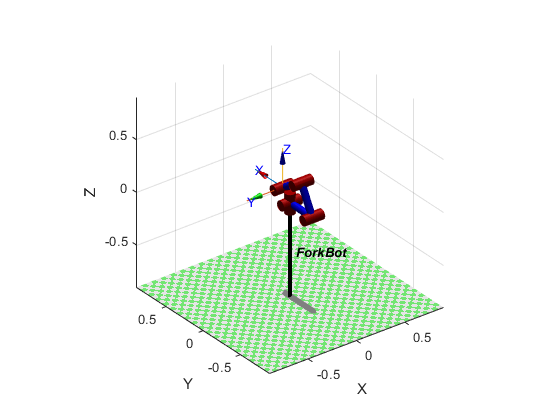


robot.plot(qf)


qcJ = [0 0 0 0 0]           %% alle ledd rett ut i x rettning

qcJ =      0     0     0     0     0


J = robot.jacob0(qcJ)

J =          0         0         0         0         0
    0.9000    0.0000    0.0000    0.0000         0
         0    0.9000    0.6000    0.3000         0
         0         0         0         0         0
         0   -1.0000   -1.0000   -1.0000   -1.0000
    1.0000    0.0000    0.0000    0.0000    0.0000


tau = J' * [0 0 8 0 0 0]';  %% regner ut wrench
tau'

ans =          0    7.2000    4.8000    2.4000         0
